# Homework #4

## Problem 1 (25 points) 

In this problem, we study “Markov Chains”: mathematical models used to describe a variety of processes ranging from stock market prices and supply chains to charge transfer in membrane ion channel proteins.

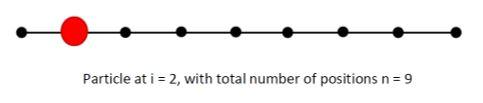

A particle moves along a 1-dimensional grid. The particle can only occupy one of n  discrete positions, i = 1,2,...n. From step t to t + 1, where t = 0,1,2,3,..., the particle moves according to the following rules: 

• If the particle is on the left boundary (i =1) , the probability of the particle staying still is 2/3, and the probability of moving right by one position is 1/3. 

• If the particle is on the right boundary (i = n), the probability of the particle staying still is 2/3, and the probability of moving left by one position is 1/3. 

• If the particle is not on the boundaries, the probability of the particle staying still is 1/2, and the probabilities of moving to the left or right by one position are both 1/4. 

The probabilities of the particle being in each of the n positions at step t is represented by the 1×n vector $x_t$. (Note that the subscript $t$ represents the step number of $x$, not an element of $x$.)  At the next step $t+1$, the particle’s probability vector transitions according to $x_{t+1} =x_t \mathbf{P}$, where $\mathbf{P}$ is an n×n matrix.  $\mathbf{P}$ is called the state transition matrix, and the element ${\mathbf{P}}_{\textrm{ij}}$ represents the probability of transition from position i to position j in a single step. 

a) (5 points) For n = 4, write down the state transition matrix $\mathbf{P}$.  Test its functioning on two simple examples to see that it gives reasonable results. 

clear all;
% Put your work below
% x_t = array w size (1,n); x at step t, the probabilities of each position
% P = array w size (n,n); the state transition matrix, P_ij is probability
% of transition from i to j in a single step

% let n=4
P = [2/3 1/3 0 0;
    1/4 1/2 1/4 0;
    0 1/4 1/2 1/4;
    0 0 1/3 2/3;];

b) (5 points)  At step t = 0, the particle is located at i = 2 with probability 1. If the number of positions is n = 4, compute $x_3$ (which is the probability at time step $t=3$. Then verify that the sum of the elements of $x_3$ is one.  Finally, plot the probability mass function for the location of the particle at $t=3$.  

x0 = [0  1  0  0];
% Put your work below
x1 = x0*P;
x2 = x1*P;
x3 = x2*P;
sum_elem_x3 = sum(x3)

sum_elem_x3 = 1.0000

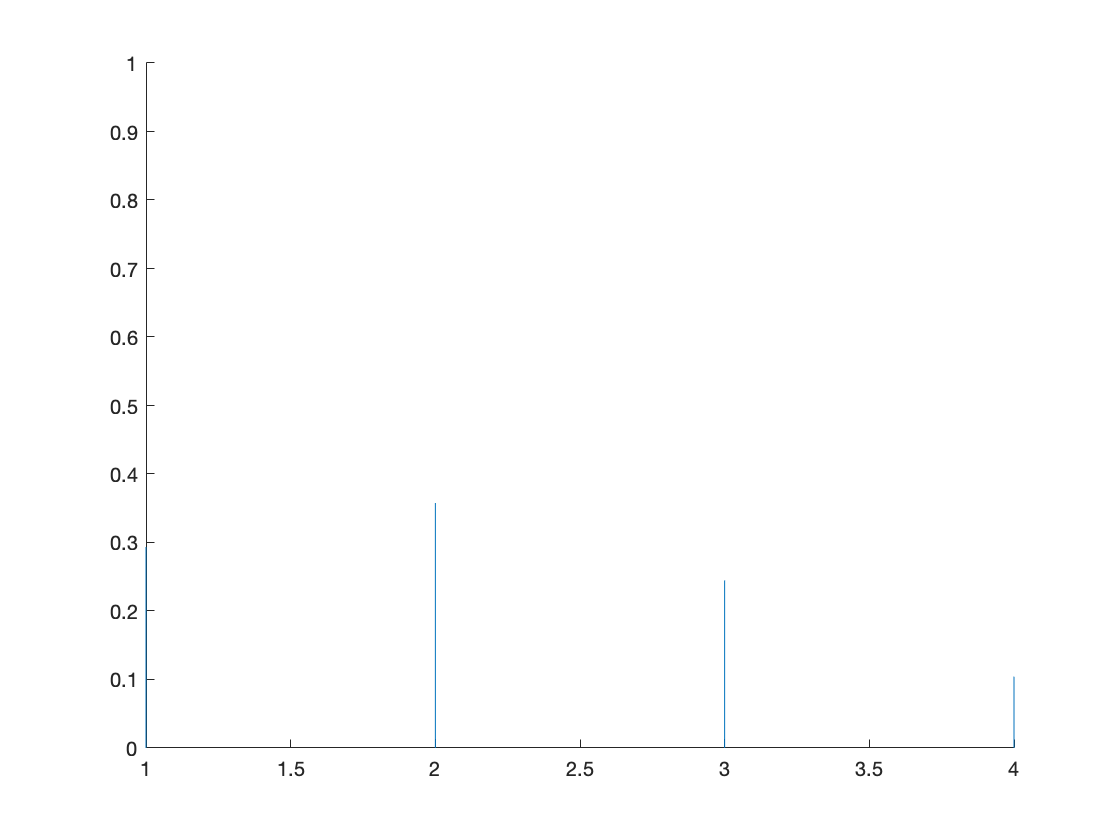

line([1 1],[0 x3(1)])
hold on
line([2 2],[0 x3(2)])
line([3 3],[0 x3(3)])
line([4 4],[0 x3(4)])
ylim([0 1])
hold off

c) (10 points) Write a short block of code that creates the state transition matrix $\mathbf{P}$ for a positive integer n ≥ 2. 

n=100; % This value could be any integer two or greater
% Put your code here
P = zeros(n);
for i = 1:n
    for j = 1:n
        if i~=1 && i~=n
            if i==j
                P(i,j)=1/2;
            elseif abs(i-j)==1
                P(i,j)=1/4;
            end
        elseif i==j
            P(i,j)=2/3;
        elseif abs(i-j)==1
            P(i,j)=1/3;
        end
    end
end
P;

d) (5 points)  For problem size n = 100, ﬁnd the state transition matrix for 1000 transitions ${\mathbf{P}}^{1000}$  and the corresponding probability vector $x_{1000}$ (start the particle such that at step $t=0$ the particle is located at location i = 2 with probability 1).   Use stem() to plot the probability mass function of the particle’s location after 1000 transitions. 

NOTE: You can copy and modify text from part (c) above.

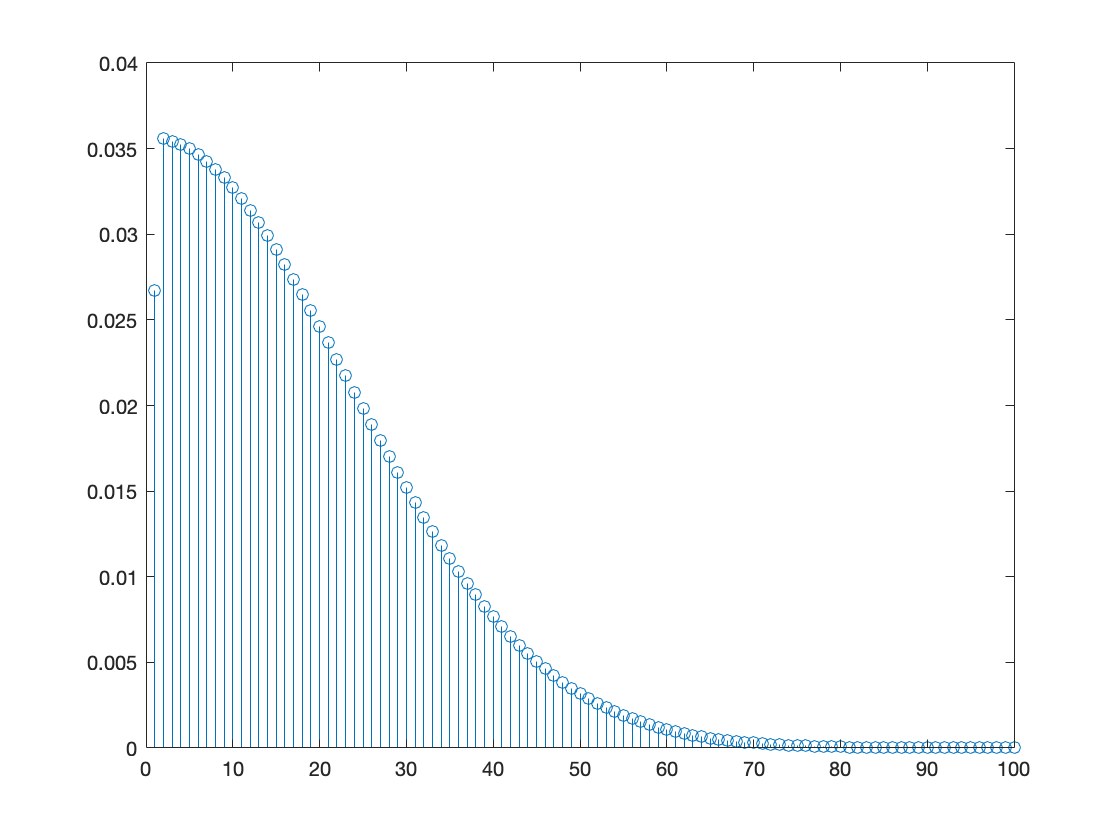

% Put your code here
x_i = zeros(1,100);
x_i(2)=1;
trans = 1000;
for i = 1:trans
    x_i = x_i*P;
end
ylim = [0 max(x_i)];
stem(1:100,x_i)

## Problem 2 (15 points) 

A two-dimensional shape is described by the coordinates below.  

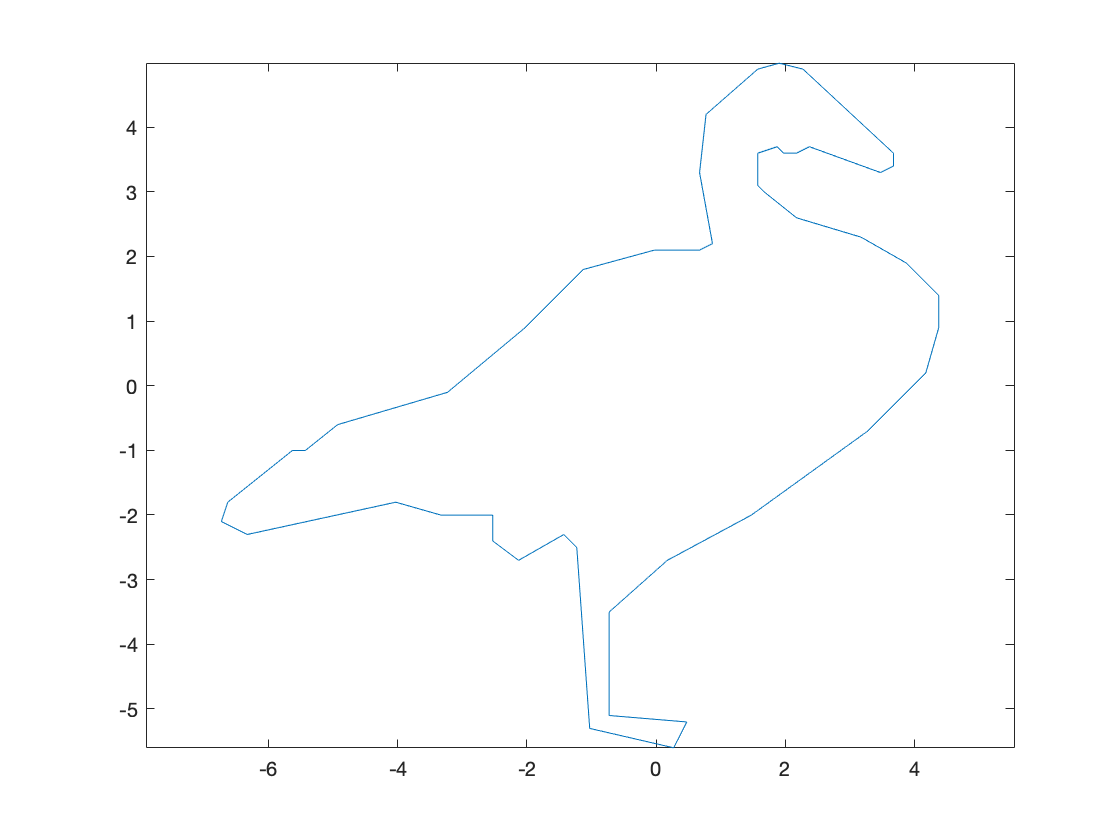

clear all
close all
% Here is a desription of the geometry in meters
goose=load_goose();
plot(goose(:,1),goose(:,2))
axis equal

a) (5 points) Compute the cross sectional area of the shape.  HINT:  One option applicable to integration over a region with non-rectangular two dimensional boundaries is described in the course notes "M2_Integration_two_dimensions.mlx" in section 2.11

% Put your code below
% x = goose(:,1)
% y = goose(:,2)
syms t x_i x_ip y_i y_ip % Here I'm using x_i and x_ip to represent x(i) and x(i+1)
x_goose = goose(:,1);
y_goose = goose(:,2);
x = x_i+(x_ip-x_i)*t;
y = y_i+(y_ip-y_i)*t;
for i=1:length(x_goose)-1
    int_Green(i)=(1/2)*(x_goose(i)*y_goose(i+1)-x_goose(i+1)*y_goose(i));
end
A=sum(int_Green)

A = 37.7777

A2 = polyarea(x_goose,y_goose)

A2 = 37.7777

b) (10 points) Compute the centroid location of the goose.  HINT:  One option is described in the course notes "M2_Integration_two_dimensions.mlx" in section 2.13

% Put your code below
for i=1:length(x_goose)-1
    y_cent(i)=(x_goose(i)-x_goose(i+1))*(y_goose(i)^2 +y_goose(i)*y_goose(i+1)+y_goose(i+1)^2);
    x_cent(i)=(y_goose(i)-y_goose(i+1))*(x_goose(i)^2 +x_goose(i)*x_goose(i+1)+x_goose(i+1)^2);
end
yc = sum(y_cent)/(6*A)

yc = 0.0044

xc = sum(x_cent)/(6*A)

xc = 0.0444

## Problem 3 (25 points) 

##                                                           Spring-Mass Systems with Many Elements 

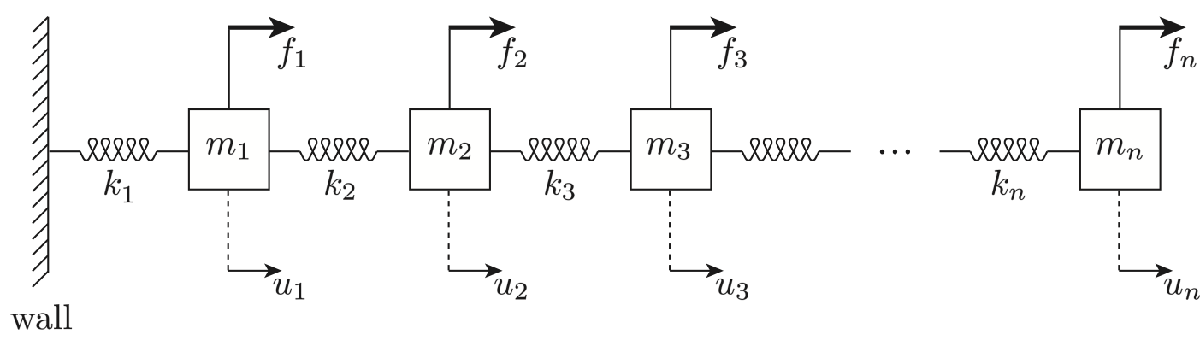

The figure above describes a system of $n$ springs and $n$ masses. The arrows labeled with $f_1$, $f_2$ and so on represent the forces applied to each mass. The arrows labeled with $u_1$, $u_2$ and so on represent the displacement of each mass, measured from the **equilibrium position** (in which all $f_i$'s are zero and hence the spring forces are zero). When we analyze these systems, you can imagine that the **forces are specified** (and therefore their values are known) and that the **displacements are unknown** and we seek to find a solution for them. In other cases, you can imagine that the displacements are specified (and therefore their values are known) and that the forces are unknown and we seek to find a solution for them. In either case, an early step toward a solution is to write a system of equations in the matrix form


$$\begin{array}{c}
\left(\begin{array}{c}
k_1 + k_2            &   - k_2 \\
 - k_2       & k_2 + k_3        &   - k_3  & & & \mbox{{0}} \\
                            & -k_3      & k_3 + k_4                  &   - k_4 \\
                            											\\	
                            &              &  \ddots                       & \ddots             & \ddots\\
                 &  0      &       & &  &                 &     \\	
                            &               &                                  &                &         &                  &    - k_n \\
                            &               &                                   &                &         &   -k_n               & k_n
\end{array}\right)
& 
\left(\begin{array}{c}
u_1 \\ u_2 \\ u_3 \\ \\ \vdots \\ \\u_{n-1} \\u_n
\end{array}\right)
&
=
&
\left(\begin{array}{c}
f_1 \\ f_2 \\ f_3 \\ \\ \vdots \\ \\f_{n-1} \\f_n
\end{array}\right)
\\
K & u & & f
\\
n\times n & n\times 1 & & n\times 1

\end{array}$$


The block of code below creates the stiffness matrix $K$ for a scenario with $n=9$ and the array of **spring stiffnesses** given a vector named "springs". The MATAB variable name for the stiffness matrix is `K`.

clear; close all; clc
%
n=9; % This value represents the number of springs
springs=[2.1 1.3 3.5 5.1 7.5 0.5 9.3 0.8 5.7]; % Individual spring stiffnesses
K=zeros(n,n); % Start off with all zeros
for i=1:n-1 % Fill in the main diagonal except the last one
    K(i,i)=springs(i)+springs(i+1); 
end
K(n,n)=springs(n); % Now finish with the last one
for i=1:n-1 % Fill in the super and sub diagonal
    K(i,i+1)=-springs(i+1); % super
    K(i+1,i)=-springs(i+1); % sub
end
K

K =     3.4000   -1.3000         0         0         0         0         0         0         0
   -1.3000    4.8000   -3.5000         0         0         0         0         0         0
         0   -3.5000    8.6000   -5.1000         0         0         0         0         0
         0         0   -5.1000   12.6000   -7.5000         0         0         0         0
         0         0         0   -7.5000    8.0000   -0.5000         0         0         0
         0         0         0         0   -0.5000    9.8000   -9.3000         0         0
         0         0         0         0         0   -9.3000   10.1000   -0.8000         0
         0         0         0         0         0         0   -0.8000    6.5000   -5.7000
         0         0         0         0         0         0         0   -5.7000    5.7000


a) (2 points) Write a short block of code that uses the stiffness matrix $K$ for detemining the forces needed to give rise to one unit greater displacement of every mass compared to each previous one. Name your vector f_a.

% Your YOUR code here:
%
u=[1 2 3 4 5 6 7 8 9]'; % This displacement is what we want to attain
f_a = K*u

f_a =     0.8000
   -2.2000
   -1.6000
   -2.4000
    7.0000
   -8.8000
    8.5000
   -4.9000
    5.7000


b) (3 points) Write a short block of code that uses the stiffness matrix $K$ for detemining the displacement if one Newton of force is applied to every mass. Name your vector u_b.  

**HINT**:  You can use "inv" or "\"

% Your YOUR code here:
%
f=[1 1 1 1 1 1 1 1 1]'; % Individual spring stiffnesses (lower case k)
u_b = K\f

u_b =     4.2857
   10.4396
   12.4396
   13.6160
   14.2827
   22.2827
   22.6053
   25.1053
   25.2807


c) (4 points) This matrix $K$ has a number of noteworthy properties. First, and perhaps most important from a computational perspective, $K$ is ***sparse***: it has mostly zero entries, since only "nearest neighbor'' connections affect a spring's deflection and the resulting force (if springs only connect adjacent masses). Characterize the sparseness of your K matrix as a function of $n$ by computing the fraction of zero entries in K (number of zero entries divided by the number of total entries) and store the result in a variable named "`fraction_zero_entries`". 

% Your YOUR code here:
sum = 0;
for i = 1:n
    for j = 1:n
        if K(i,j)==0
            sum = sum+1;
        end
    end
end
fraction_zero_entries= sum/(n*n)

fraction_zero_entries = 0.6914

d) (4 points) Another noteworthy property is that $K$ is ***tri-diagonal**** --*  all entries above and below the center three diagonals are zero. Write a short script that will check whether K has this property and store the result in a logical variable named "`tridiagonal`". Your code should work correctly for the specific K matrix from part (a) and for any square matrix named K (9x9, 20x20, or whatever size).  Please do not use the MATLAB built-in named "isbanded".

% Your YOUR code here:
tridiagonal = true;
for i = 1:n
    for j = 1:n
        if abs(j-i)>1 && K(i,j)~=0
            tridiagonal = false;
        end
    end
end
tridiagonal

tridiagonal = logical
   1


e) (3 points) You'll see that for the example given here (and indeed for any set of k values you might choose), $K$ is **symmetric*** --*  its entries off the main diagonal are all equal to the ones on the opposite side of the main diagonal. This can be expressed simply as `K(i,j)=K(j,i)` for all i, 1 to n, and all j, 1 to n. Write a short code that will store the value 1 or true in a logical variable named "`symmetric`". Your code should work correctly for the specific K matrix from part (a) and for any square matrix named K (9x9, 20x20, or whatever size).  Please do not use the MATLAB built-in named "issymmetric".

% Your YOUR code here:
symmetric = true;
for i = 1:n
    for j = 1:n
        if K(i,j)~=K(j,i)
            symmetric = false;
        end
    end
end
symmetric

symmetric = logical
   1


f) (4 points) Another noteworthy property is that $K$ is ***positive definite**** --*  for any vector of displacements $u$, $u^T \cdot K\cdot u>0$ except for the null case with all the displacements in $u$ being zero.  Write a short script that will spot check whether $u^T \cdot K\cdot u>0$ for 100 vectors of random displacements ranging from -1 unit to 1 unit.  Store the result in a logical variable named "passed_tests". Your code should work correctly for the specific K matrix from part (a) and for any square matrix named K (9x9, 20x20, or whatever size). 

u=rand(9,1)*2-1 % This is a random displacement vector ranging from -1 to 1

u =     0.1188
   -0.6442
   -0.7301
   -0.5932
   -0.9771
    0.7092
    0.2168
   -0.9324
   -0.8367


% Your YOUR code here:
n = 100;
K_size = length(K);
passed_tests = true;
for i = 1:n
    u = rand(K_size,K_size)*2-1;
    if u'*K*u<=0
        passed_tests = false;
    end
end
passed_tests

passed_tests = logical
   1


g) (5 points) Consider the situation where spring(1)=0 (spring 1 is extremely compliant or does not exist). Determine two different mass displacements consistent with the forcing ( $f_1=-1 $ and $f_2=0  ...f_8=0$and $f_9=1$). Name them u_1 and u_2.  Explain what you found both physically and mathematically.

f=[-1 0 0 0 0 0 0 0 1]'; % This is the same force vector as above
% Your YOUR code here:
n=9; % This value represents the number of springs
springs=[0 1.3 3.5 5.1 7.5 0.5 9.3 0.8 5.7]; % Individual spring stiffnesses
K=zeros(n,n); % Start off with all zeros
for i=1:n-1 % Fill in the main diagonal except the last one
    K(i,i)=springs(i)+springs(i+1); 
end
K(n,n)=springs(n); % Now finish with the last one
for i=1:n-1 % Fill in the super and sub diagonal
    K(i,i+1)=-springs(i+1); % super
    K(i+1,i)=-springs(i+1); % sub
end
K;
rank_of_K = rank(K)

rank_of_K = 8

u_1 = K\f

u_b =    -4.5423
   -3.7731
   -3.4874
   -3.2913
   -3.1580
   -1.1580
   -1.0504
    0.1996
    0.3750


u_2 = inv(K)*f

u_c =    -4.0000
   -3.2500
   -3.0000
   -2.7500
   -2.6250
   -0.6250
   -0.5000
    0.7500
    0.8750


u1 = -4.5423

u2 = -3.7731

## Problem 4 (15 points) 

a) (5 points) Consider the multiplication of matrix A of size MxN with matrix B of size NxP (`A*B` in Matlab). Assuming M, N and P are large enough for leading order terms to be dominant, what is the order of the number of FLOPS associated with this product? Briefly explain how you obtained your answer.

% Write your answer as a comment here:
% number of FLOPS = 2*M*N*P - M*P
% there are M*N*P multiplications and M*P*(N-1) additions, resulting in a
% total of 2*M*N*P - M*P FLOPS
% to elaborate, the product will have the dimensions (M,P).
% to calculate one element in the product vector, one must conduct N
% multiplications and N-1 additions. This results in a total of 2MPN-MP
% FLOPS.


b) (5 points) Consider the elementwise multiplication of matrix A of size MxN with matrix C (of the same size) (`A.*C` in Matlab). Assuming M and N is large enough for leading order terms to be dominant, what is the order  of the number of FLOPS associated with this product? 

% Write your answer as a comment here:
% number of FLOPS = M*N as the (i,j)th element of the product vector of size M*N
% is found by multiplying the A(i,j)*B(i,j) elements, where i and j range
% from 1 to M and 1 to N respectively.

c) (5 points)  Consider the diagonal matrix A of size 4x4, with diagonal terms $A_{11}=a$, $A_{22}=b$, $A_{33}=c$ and $A_{44}=d$. Write down the non-zero elements of matrix $A^{-1}$. Briefly explain how you arrived at your answer.

% Write your answer as a comment here:
n=4;
A = zeros(n);
a=1;
b=2;
c=3;
d=4;
A(1,1)=a;
A(2,2)=b;
A(3,3)=c;
A(4,4)=d;
A_inv = inv(A);

A_inv =     1.0000         0         0         0
         0    0.5000         0         0
         0         0    0.3333         0
         0         0         0    0.2500


for i = 1:size(A_inv)
    for j = 1:size(A_inv)
        if A_inv(i,j)~=0
            A_inv(i,j)
        end
    end
end

ans = 1

ans = 0.5000

ans = 0.3333

ans = 0.2500

## Problem 5 (20 points) 

In this problem, you will explore how matrices act on 3D geometry.  Please go get the file 'BabyYoda.mat' from Canvas and place it in your current directory.

load('BabyYoda.mat')
plot3(BabyYoda(1,:),BabyYoda(2,:),BabyYoda(3,:),'g.')
axis equal
hold on

a) (5 points) Pre-multiply the 3 by 4000 matrix BabyYoda by a rotation matrix `[cosd(35) 0 -sind(35); -sind(35) 0 cosd(35); 0 1 0].  `Place the result in a variable called Yoda`_rotation `and plot using black dots.

% Your code here
Yoda_rotation = [cosd(35) 0 -sind(35); -sind(35) 0 cosd(35); 0 1 0]*BabyYoda;
plot3(Yoda_rotation(1,:),Yoda_rotation(2,:),Yoda_rotation(3,:),'k.')
axis equal

b) (5 points) Plot the vectors `[1 -2 0]'` and `[1 3 1]'`.  In other words, please draw two lines from the origin to these two x y z locations.  Plot at least one other vector in the same plane occupied by the first two vectors.  

% Your code here
Vector1 = [1 -2 0]';
Vector2 = [1 3 1]';
plot3([0 Vector1(1)], [0, Vector1(2)], [0, Vector1(3)])
plot3([0 Vector2(1)], [0, Vector2(2)], [0, Vector2(3)])

c) (5 points) Form a matrix `B=[1 -2 0; 1 3 1]'` and a projection matrix `P=B*inv(B'*B)*B'` .  Compute `P*BabyYoda` and store the result in a variable called Yoda`_projection`.  Make a plot to show Yoda`_projection` (using magenta dots).  You’ll see the projection of BabyYoda onto the plane containing the vectors from part the previous sub-question.

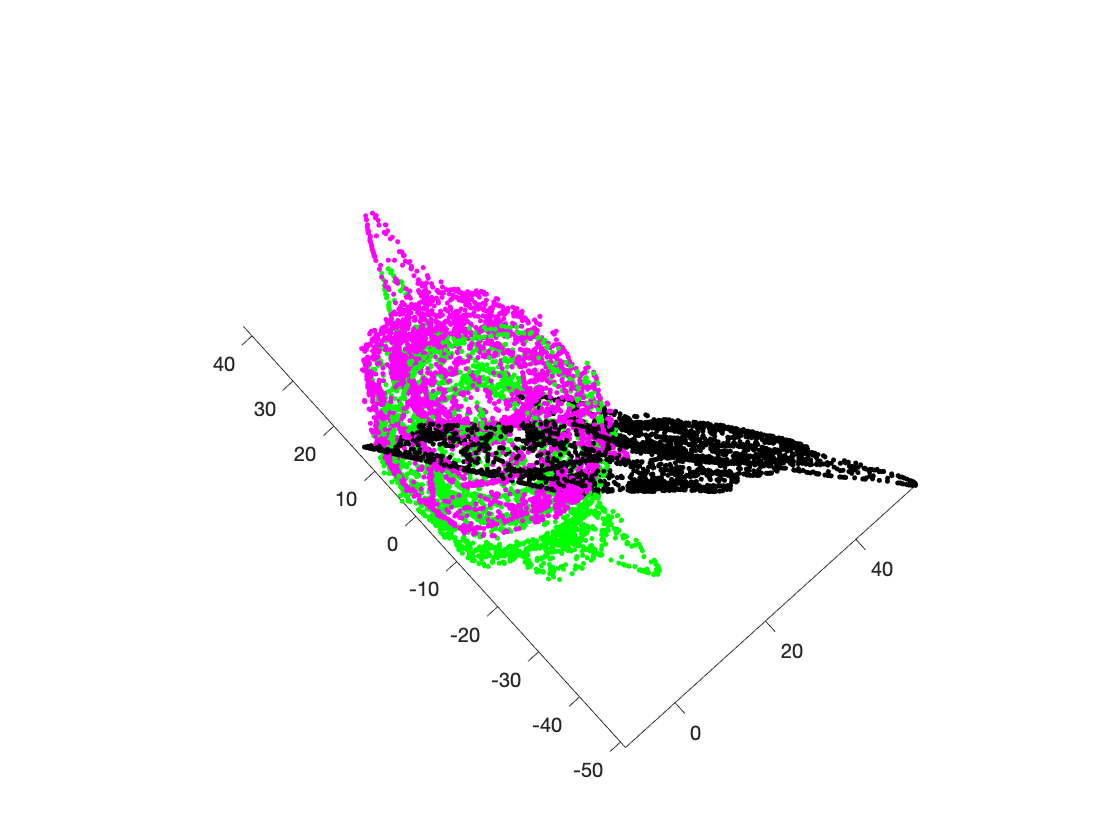

% Your code here
B=[1 -2 0; 1 3 1]';
P=B*inv(B'*B)*B';
Yoda_projection = P*BabyYoda;
plot3(Yoda_projection(1,:),Yoda_projection(2,:),Yoda_projection(3,:),'m.')

d) (5 points) Baby Yoda seems too short.  Premultiply BabyYoda by [1 0 0; 0 1 0; 0 0 3] and store in TallYoda and plot using red dots.  Be sure to show axis equal so that you can perceive the effect.

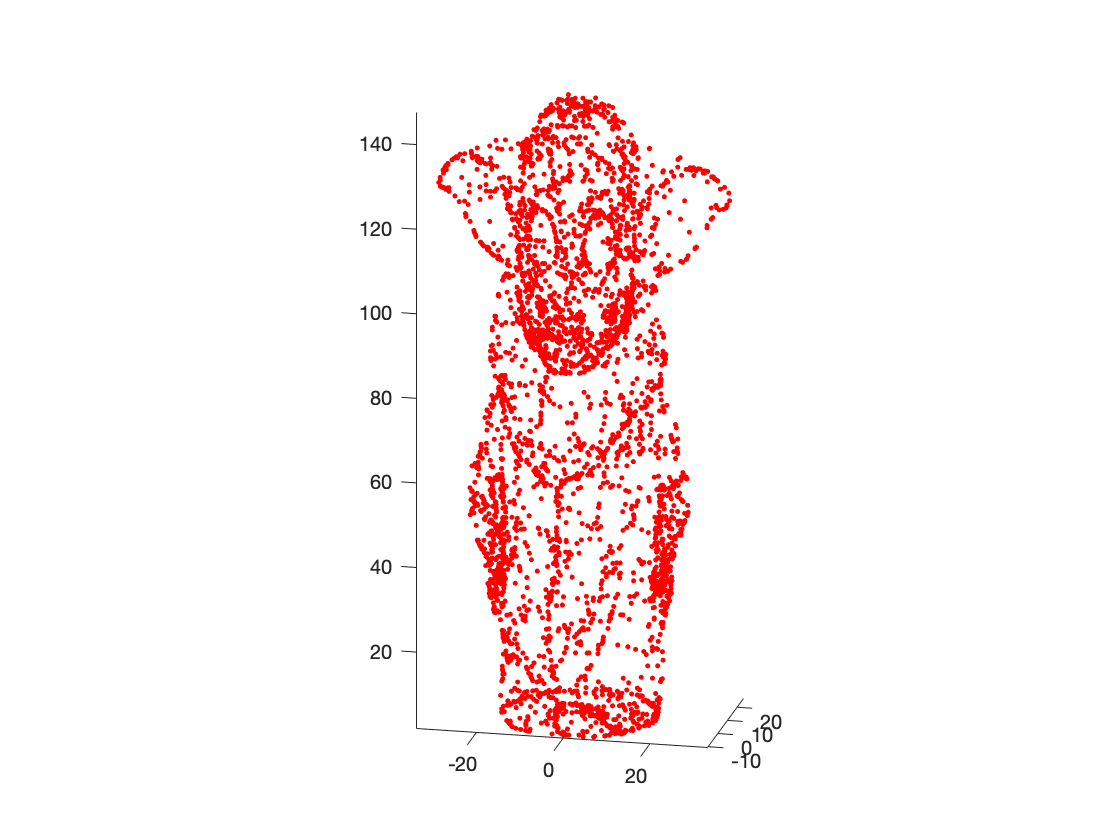

close
% Your code here
TallYoda = [1 0 0; 0 1 0; 0 0 3]*BabyYoda;
plot3(TallYoda(1,:),TallYoda(2,:),TallYoda(3,:),'r.')
axis equal

function [goose] = load_goose()
% loads geometry into the workspace for problem 1

goose=flip([0.271 -5.602;
    -1.029 -5.302;
    -1.229 -2.502;
    -1.429 -2.302;
    -2.129 -2.702;
    -2.529 -2.402;
    -2.529 -2.002;
    -3.329 -2.002;
    -4.029 -1.802;
    -6.329 -2.302;
    -6.729 -2.102;
    -6.629 -1.802;
    -5.629 -1.002;
    -5.429 -1.002;
    -4.929 -0.602;
    -3.229 -0.102;
    -2.029 0.898;
    -1.129 1.798;
    -0.029 2.098;
    0.671 2.098;
    0.871 2.198;
    0.671 3.298;
    0.771 4.198;
    1.571 4.898;
    1.903 4.990;
    2.271 4.898;
    3.671 3.598;
    3.671 3.398;
    3.471 3.298;
    2.371 3.698;
    2.171 3.598;
    1.971 3.598;
    1.871 3.698;
    1.571 3.598;
    1.571 3.098;
    1.671 2.998;
    2.171 2.598;
    3.171 2.298;
    3.871 1.898;
    4.371 1.398;
    4.371 0.898;
    4.171 0.198;
    3.271 -0.702;
    1.471 -2.002;
    0.171 -2.702;
    -0.729 -3.502;
    -0.729 -5.102;
    0.473 -5.202;
    0.271 -5.602]);
end % load_goose

